# Plotting LIDAR Range Data

Objective: This script reads the LIDAR data from the CreateRobot object (*robotObj*) and plots the raw output for evaluation. The LIDAR range is the distance an obstacle is away from the sensor at the corresponding LIDAR angle.

Cheat Sheet: When working with the Create robot's LIDAR sensor in your programs, you will use properties of the CreateRobot object (*robotObj*) that contain values such as the sensor's angle range, maximum range, number of measurements and the angle of the LIDAR sweep that each reading is associated with. To capture the data from the LIDAR sensor, you will use the function *genLidar(robotObj, map*). This function generates a reading for the LIDAR sensor and returns a row vector of range measurements.

Below is the list of CreateRobot LIDAR sensor properties that you will use in your programs when working with the LIDAR sensor:

- robotObj.angRangeLidar: Angular range of LIDAR sensor 

- robotObj.rangeLidar: Maxium range of LIDAR sensor

- robotObj.numPtsLidar: Number of points (measurements) in LIDAR sensing range

- robotObj.angleArray: Array of LIDAR angles

For more information, refer to the CreateRobot documentation and investigate the different properties and methods associated with the LIDAR sensor.  

help CreateRobot %in Command Window

  Creates definition of class, instances of which will include all
  properties and controls associated with a single CreateRobot robot

    Documentation for CreateRobot



Helper Functions used in this exercise:

- plot_lidar*:* plots the LIDAR output (range vs. angle)

**EXERCISE:**

After loading the map and pressing the "Read Sensors" button in the Simulator, you will have access to the CreateRobot object (*robotObj***) **that represents the current state of the robot. 

Complete the code below to:

- Initialize the LIDAR constants. 

- Get the LIDAR sensor reading.

**COMPLETE THE CODE BELOW**

%1. Get LIDAR Constants
angRangeLidar = robotObj.angRangeLidar; % YOUR CODE HERE
maxRangeLidar = robotObj.rangeLidar; % YOUR CODE HERE
numPtsLidar = robotObj.numPtsLidar; % YOUR CODE HERE
angleArrayLidar= robotObj.angleArray; % YOUR CODE HERE

% 2. Read the LIDAR sensor
lidarReadingRangeVector= genLidar(robotObj, map); % YOUR CODE HERE


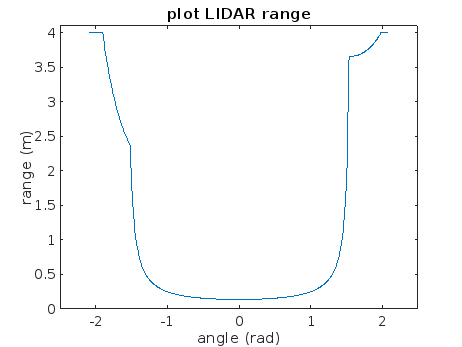

% --- Plot ----
plot_lidar(angleArrayLidar, lidarReadingRangeVector); 

Expected Results:

If you've read the LIDAR information correctly from the CreateRobot object, the plot will show the raw LIDAR range vs. the LIDAR angle. A LIDAR angle of 0 represents the LIDAR reading directly in front of the robot. Does the range output correspond to the estimated distance of an object directly in front of the robot?

Check your Comprehension:

Move the robot around the map facing different obstacles and rerun this exercise. Does the range output make sense based on where you place the robot? What if no walls are in the field of view (sensor footprint) of the LIDAR, what happens?